% STEP #1: Prompting user for maze size
maze_size = input("Enter a size for your maze: ");
maze_labels = zeros(maze_size, maze_size);
for i=1:maze_size
    for j=1:maze_size
        maze_labels(i,j) = (i-1)*maze_size+j;
    end
end

maze_labels;
walls_down = 0;

% We will be using Kruskal's algorithm to generate a maze!
% Join cells that are NOT in the same set by removing edges, then 
% formula for finding neighbor edges: self num, selfnum + 1
% self_num + maze_num + 1, self_num+maze_size+2
Db = delsq(numgrid('S',maze_size+3));
B = graph(logical(Db),'omitselfloops')

B =   graph with properties:

    Edges: [144×1 table]
    Nodes: [81×0 table]


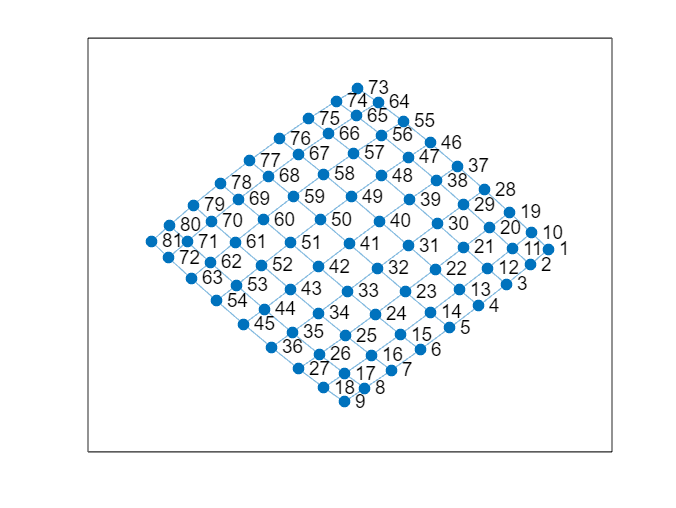

plot(B)

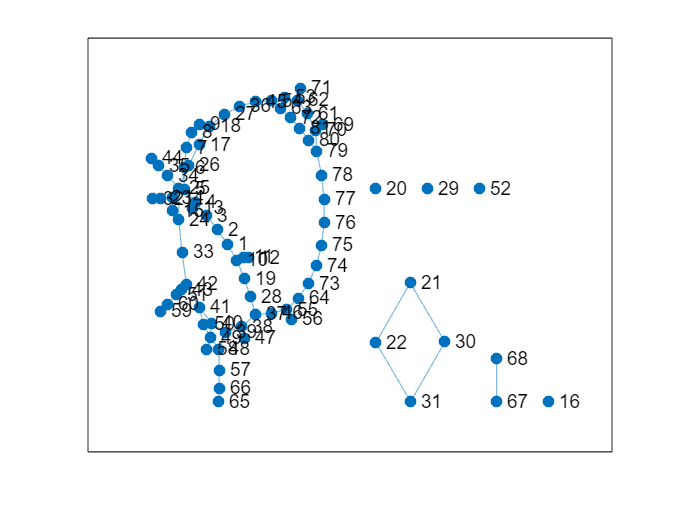


% Removing walls until #walls_down < #cells - 1
while walls_down < maze_size^2 - 1
    % pick random cell
    x = randi([1, maze_size]);
    y = randi([1, maze_size]);

    % find neighbors of the cell
    neighbors = find_neighbors(x, y, maze_size);
    % pick a random neighbor
    n = randi([1, length(neighbors)]);
    % make neighbor x and neighbor y
    current_neighbor = neighbors(n, :);
    nx = current_neighbor(1);
    ny = current_neighbor(2);

    share_coord = current_neighbor-[x, y];
    nodes = get_nodes(x, y, maze_size);

    % find the wall the neighbors share and try to take it down
    % WALL HAS SAME X coord
    if share_coord(1) == 0

        % Wall is below cell
        if share_coord(2) < 0
            if findedge(B, nodes(1), nodes(2))
                % if these two cells are not yet connected with a path..
                if maze_labels(nx, ny) ~= maze_labels(x, y)
                    % Connect them, then make their number the same
                    maze_labels(nx, ny) = maze_labels(x, y);
                    B = rmedge(B, nodes(1), nodes(2));

                    % increment walls you have taken down
                    walls_down = walls_down +1;
                else
                    continue
                end 
            else
                continue
            end 
        % wall is above cell
        else 
            if findedge(B, nodes(3), nodes(4))
               if maze_labels(nx, ny) ~= maze_labels(x, y)
                    maze_labels(nx, ny) = maze_labels(x, y);
                    B = rmedge(B, nodes(3), nodes(4));
                    walls_down = walls_down +1;
                else 
                    continue
                end 
            else
                continue
            end 
        end

    % SAME Y COORD
    else 
        % this means that neighbor is on the left
        if share_coord(1) < 0
            if findedge(B, nodes(1), nodes(3))
                if maze_labels(nx, ny) ~= maze_labels(x, y)
                    maze_labels(nx, ny) = maze_labels(x, y);
                    B = rmedge(B, nodes(1), nodes(3));

                    walls_down = walls_down +1;
                else
                    continue
                end 
            else
                continue
            end 
        % neighbor is on the right
        else 
            if findedge(B, nodes(2), nodes(4))
                if maze_labels(nx, ny) ~= maze_labels(x, y)
                    maze_labels(nx, ny) = maze_labels(x, y);
                    B = rmedge(B, nodes(2), nodes(4));
                    walls_down = walls_down +1;
                else 
                    continue
                end 
            else
                continue
            end 
        end
    end
end 

% iterate through all the nodes
x_to = [];
x_from = [];
y_to = [];
y_from = [];

for node=1:(maze_size+1)^2
    coord = node_to_coord(node, maze_size);
    node_neighbors = get_node_neighbors(node, maze_size);

    for i=1:length(node_neighbors)
        if findedge(B, node, node_neighbors(i)) ~= 0
            nb_coord = node_to_coord(node_neighbors(i), maze_size);
            x_from = [x_from, coord(1)];
            y_from = [y_from, coord(2)];
            x_to = [x_to, nb_coord(1)];
            y_to = [y_to, nb_coord(2)];
        else
            continue

        end 
    end 
end 

plot(B)

findedge(B, 9, 8)

ans = 11

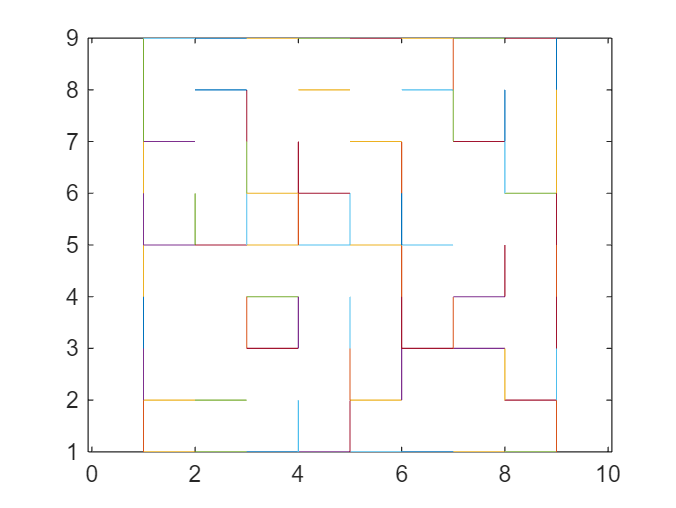

plot([x_from; x_to], [y_from; y_to])
xlim([-1, 4])
axis equal

function result = find_neighbors(x, y, matrix_size)
result = [];
   if x == matrix_size
       row_end = 0;
       row_start = -1;
   elseif x == 1
       row_end = 1;
       row_start = 0;
   else
       row_start = -1;
       row_end = 1;
   end 

   if y == matrix_size
       col_end = 0;
       col_start = -1;
   elseif y == 1
       col_end = 1;
       col_start = 0;
   else
       col_start = -1;
       col_end = 1;
   end 
   
   %add the new x coords
   for new_row=x+row_start:x+row_end
       if new_row == x
           continue
       else 
           result = [result; [new_row, y]];
       end  
   end 

   %add the new y coords
   for new_col = y+col_start:y+col_end
       if new_col == y
           continue
       else 
           result = [result; [x, new_col]];
       end 
   end 
end 

% GET NEIGHBORS OF A NODE
function node_neighbors = get_node_neighbors(node, maze_size)
maze_num = maze_size+1;
% corners
if node == 1
    node_neighbors = [2, node+maze_num];
elseif node == maze_num
    node_neighbors = [node-1, node+maze_num];
elseif node == (maze_num)^2 - maze_size
    node_neighbors = [node+1, node - (maze_num)];
elseif node == (maze_num)^2
    node_neighbors = [node-1, node-(maze_num)];

% left edge
elseif mod((node-1),(maze_size+1)) == 0
    node_neighbors = [node+1, node+maze_num, node-maze_num];
    % right edge
elseif mod(node, maze_num) == 0
    node_neighbors = [node-1, node+maze_num, node-maze_num];
    % bottom edge
elseif node <maze_num
    node_neighbors = [node+maze_num, node-1, node+1];
    % top edge
elseif node > (maze_num-1)*maze_num && node < maze_num^2
    node_neighbors = [node-maze_num, node-1, node+1];
else
    node_neighbors = [node-maze_num, node-1, node+1, node+maze_num];
end
end

function node_coord = node_to_coord(node, maze_size)
maze_num = maze_size +1;
if mod(node, maze_num) == 0
    node_x = maze_num;
    node_y = node/maze_num;
   
else
node_x = mod(node, maze_num);
node_y = floor(node/maze_num) + 1;

end 
node_coord = [node_x, node_y];
end

function nodes = get_nodes(x, y, maze_size)
nodes = [(y-1)*(maze_size+1)+x, (y-1)*(maze_size+1)+x+1,(y-1)*(maze_size+1)+x+(maze_size+1), (y-1)*(maze_size+1)+x+(maze_size+2)];
end 